# Cholesky Decomposition Correlated Bivariate Normal from IID Random Draws

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

Draw two correlated normal shocks using the MVNRND function. Draw two correlated normal shocks from uniform random variables using Cholesky Decomposition.

- [fs_cholesky_decomposition](https://fanwangecon.github.io/M4Econ/simulation/normal/htmlpdfm/fs_cholesky_decomposition.html)

- [fs_cholesky_decomposition_d5](https://fanwangecon.github.io/M4Econ/simulation/normal/htmlpdfm/fs_cholesky_decomposition_d5.html)

- [fs_bivariate_normal](https://fanwangecon.github.io/M4Econ/simulation/normal/htmlpdfm/fs_bivariate_normal.html)

## Positively Correlated Scores MVNRND

We have English and Math scores, and we draw from a bivariate normal distribution, assuming the two scores are positively correlatd. These are $x_1$ and $x_2$.

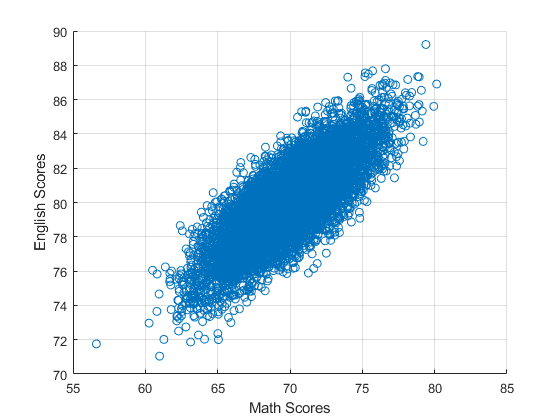

% mean, and varcov
ar_mu = [70,80];
mt_varcov = [8,5;5,5];
% Generate Scores
rng(123);
N = 10000;
mt_scores = mvnrnd(ar_mu, mt_varcov, N);
% graph
figure();
scatter(mt_scores(:,1), mt_scores(:,2));
ylabel('English Scores');
xlabel('Math Scores')
grid on;

What are the covariance and correlation statistics?

disp([num2str(cov(mt_scores(:,1), mt_scores(:,2)))]);

8.0557      5.0738
5.0738      5.0638


disp([num2str(corrcoef(mt_scores(:,1), mt_scores(:,2)))]);

      1     0.79441
0.79441           1


## Bivariate Normal from Uncorrelated Draws via Cholesky Decomposition

We can get the same results as above, without having to explicitly draw from a multivariate distribution by (For more details see [Train (2009)](https://eml.berkeley.edu/~train/distant.html)):

- Draw 2 uniform random iid vectors.

- Convert to normal iid vectors.

- Generate the test scores as a function of the two random variables, using Cholesky matrix. 

***First***, draw two uncorrelated normal random variables, with mean 0, sd 1, $\eta_1$ and $\eta_2$. 

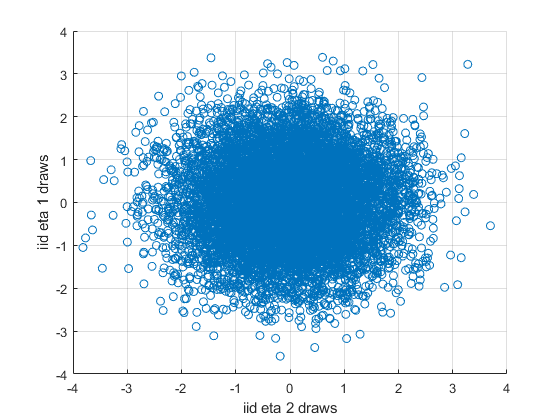

% Draw Two Uncorrelated Normal Random Variables
% use the same N as above
rng(123);
% uniform draws, uncorrelated
ar_unif_draws = rand(1,N*2);
% normal draws, english and math are uncorreated
% ar_draws_eta_1 and ar_draws_eta_2 are uncorrelated by construction
ar_normal_draws = norminv(ar_unif_draws);
ar_draws_eta_1 = ar_normal_draws(1:N);
ar_draws_eta_2 = ar_normal_draws((N+1):N*2);
% graph
figure();
scatter(ar_draws_eta_1, ar_draws_eta_2);
ylabel('iid eta 1 draws');
xlabel('iid eta 2 draws')
grid on;

% Show Mean 1, cov = 0
disp([num2str(cov(ar_draws_eta_1, ar_draws_eta_2))]);

  0.99075   0.0056929
0.0056929     0.98517


disp([num2str(corrcoef(ar_draws_eta_1, ar_draws_eta_2))]);

        1   0.0057623
0.0057623           1


***Second***, now using the variance-covariance we already have, decompose it, we will have:

- 
$$c_{aa} \thinspace,\thinspace\thinspace 0\\c_{ab} \thinspace,\thinspace\thinspace c_{bb}$$


% Choesley decompose the variance covariance matrix
mt_varcov_chol = chol(mt_varcov, 'lower');
disp([num2str(mt_varcov_chol)]);

2.8284           0
1.7678      1.3693


% The cholesky decomposed matrix factorizes the original varcov matrix
disp([num2str(mt_varcov_chol*mt_varcov_chol')]);

8           5
5           5


***Third***, We can get back to the original $x_1$ and $x_2$ variables:

- 
$$x_1 = \mu_1 + c_{aa} * \eta_1$$


- 
$$x_2 = \mu_2 + c_{ab} * \eta_1 + c_{bb} * \eta_2$$


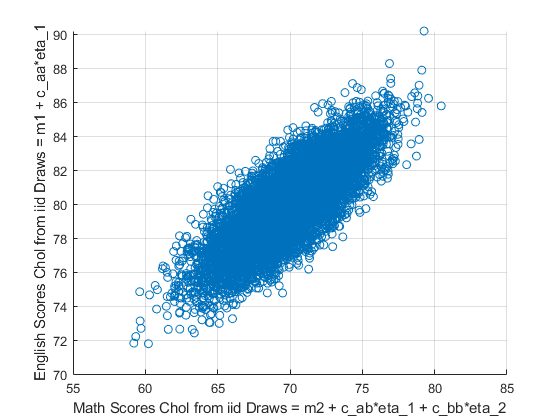

% multiple the cholesky matrix by the eta draws
mt_scores_chol = ar_mu' + mt_varcov_chol*([ar_draws_eta_1; ar_draws_eta_2]);
mt_scores_chol = mt_scores_chol';
% graph
figure();
scatter(mt_scores_chol(:,1), mt_scores_chol(:,2));
ylabel('English Scores Chol from iid Draws = m1 + c\_aa*eta\_1');
xlabel('Math Scores Chol from iid Draws = m2 + c\_ab*eta\_1 + c\_bb*eta\_2')
grid on;

disp([num2str(cov(mt_scores_chol(:,1), mt_scores_chol(:,2)))]);

 7.926      4.9758
4.9758      4.9708


disp([num2str(corrcoef(mt_scores_chol(:,1), mt_scores_chol(:,2)))]);

      1     0.79272
0.79272           1
